clear;close all;clc;
warning off;

% -------------- replace the root_path --------------
root_path = "D:\RS\NWRSBA_open_source\";
addpath(genpath(root_path));

% -------------- system config --------------
scale_camera = 13;
measurement_noise = 1;        


% -------------- generate camera param -------------
initialized_flag = false;
while ~initialized_flag
    try
        % ------ generate_multi_views_index ------
        % w : degree/s (30fps)
        % d :      m/s (30fps)
        % measurement_noise : measurement_noise
        % scale : scale (point_center to camera distance)
        % is_random_degree : true
        % ------ generate_multi_views_index end ------
%         [camera_set, p3d, p3d_gt, pram, flag] = generate_multi_views_index(60, 6, measurement_noise, scale_camera, true);
%         [camera_set_normal, p3d_normal] = generate_multi_views_index_normal_real(camera_set, p3d, pram);

        % ------ generate_degeneracy_views_pitch_index ------
        % w : degree/s (1 s = 30 frames)
        % d :      m/s (1 s = 30 frames)
        % measurement_noise : measurement_noise
        % pitch : degrees the readout angle 
        % scale : scale (point_center to camera distance)
        % is_random_degree : true
        % ------ generate_degeneracy_views_pitch_index end ------
        [camera_set, p3d, p3d_gt, pram, flag] = generate_degeneracy_views_pitch_index(60, 6, measurement_noise, 0.01, scale_camera, true);
        [camera_set_normal, p3d_normal] = generate_degeneracy_views_pitch_index_normal_real(camera_set, p3d, pram);


        if flag == 1
            disp('wd too large or scale too small');
            continue;
        end

        initialized_flag = true;
        disp('initialization success');

        % ------ get state vector ------
        gt_camera_param = raw2vec(camera_set, p3d, p3d_gt, pram, true);             
        camera_param = raw2vec(camera_set, p3d, p3d_gt, pram, false);
        % ------ get normalized state vector ------
        gt_camera_param_normal = raw2vec(camera_set_normal, p3d_normal, p3d_gt, pram, true);
        camera_normal_param = raw2vec(camera_set_normal, p3d_normal, p3d_gt, pram, false);
    catch
        disp('initialization fail error!!!');
        continue;
    end
end

% -------------- gsba --------------
refined_GSBA = GSBA(camera_param, pram, camera_set);
[refined_GSBA] = AdjustWithScale(refined_GSBA, gt_camera_param, pram);
figure
p3d_gt = getPoint(gt_camera_param, pram);
p3d = getPoint(refined_GSBA, pram);
error_gs = sum(sum((p3d_gt - p3d) .* (p3d_gt - p3d)))

error_gs = 2.5495

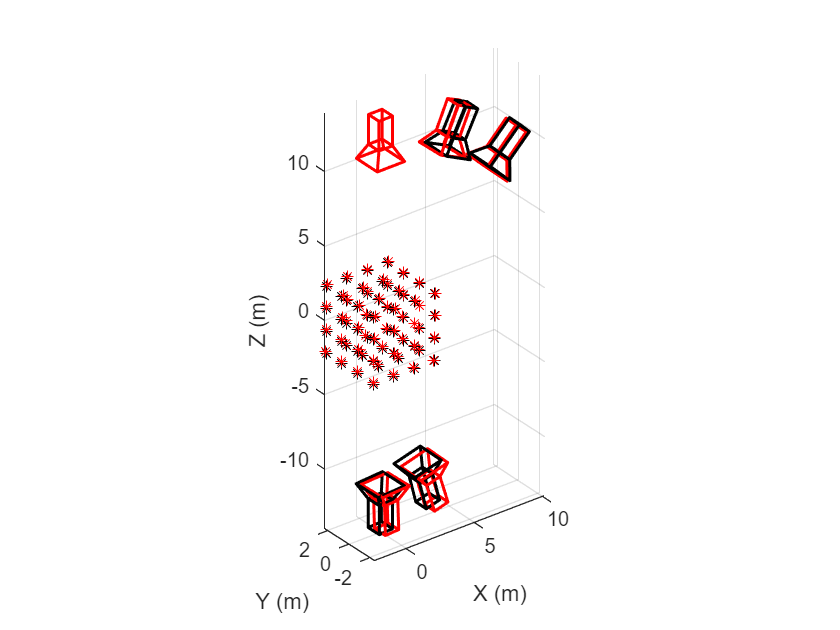

plot3d_rs(refined_GSBA, gt_camera_param, p3d_gt, p3d, pram, 'red', 'r*')


% -------------- MRSBA --------------       
[refined_RSBA] = RSBA(camera_param, pram,camera_set);
[refined_RSBA] = AdjustWithScale(refined_RSBA, gt_camera_param, pram);
figure
p3d_gt = getPoint(gt_camera_param, pram);
p3d = getPoint(refined_RSBA, pram);
error_mrsba = sum(sum((p3d_gt - p3d) .* (p3d_gt - p3d)))

error_mrsba = 691.7727

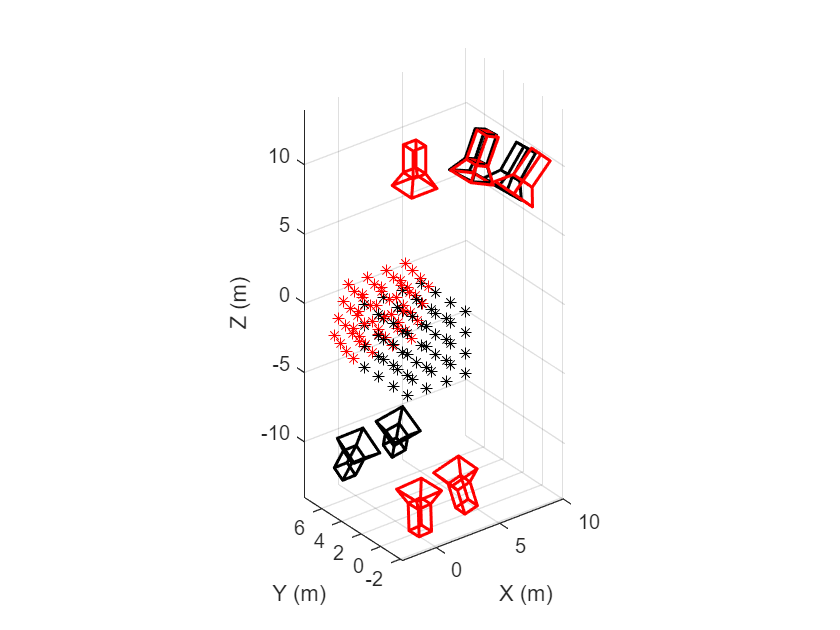

plot3d_rs(refined_RSBA, gt_camera_param, p3d_gt, p3d, pram, 'red', 'r*')

% -------------- W-RSBA --------------
[refined_RSBA_weighted] = RSBA_weighted(camera_param, pram,camera_set);
[refined_RSBA_weighted] = AdjustWithScale(refined_RSBA_weighted, gt_camera_param, pram);
figure
p3d_gt = getPoint(gt_camera_param, pram);
p3d = getPoint(refined_RSBA_weighted, pram);
error_wmrsba = sum(sum((p3d_gt - p3d) .* (p3d_gt - p3d)))

error_wmrsba = 11.7232

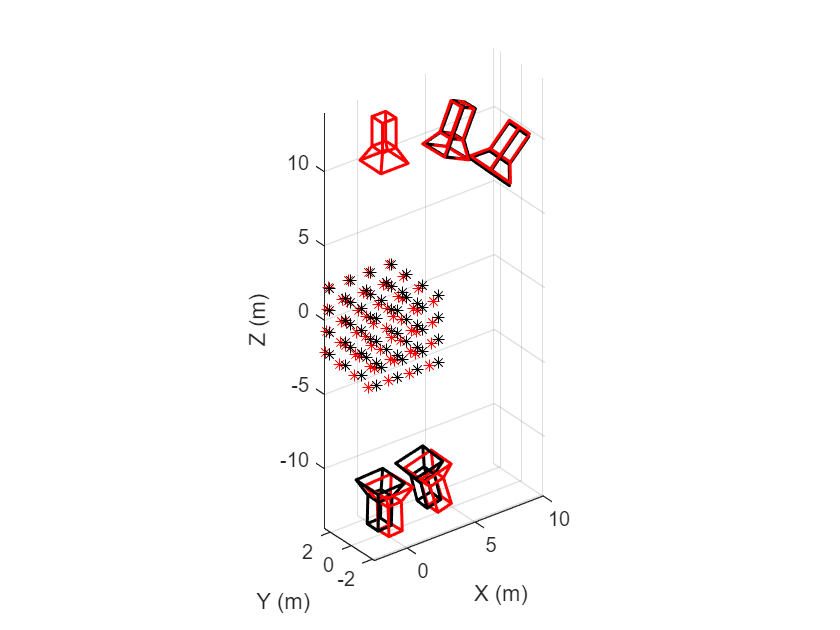

plot3d_rs(refined_RSBA_weighted, gt_camera_param, p3d_gt, p3d, pram, 'red', 'r*')


% -------------- NW-RSBA --------------      
[refined_RSBA_weighted_normal] = RSBA_weighted_normal(camera_normal_param, pram,camera_set_normal);
[refined_RSBA_weighted_normal] = AdjustWithScale(refined_RSBA_weighted_normal, gt_camera_param_normal, pram);
figure
p3d_gt = getPoint(gt_camera_param_normal, pram);
p3d = getPoint(refined_RSBA_weighted_normal, pram);
error_nwrsba = sum(sum((p3d_gt - p3d) .* (p3d_gt - p3d)))

error_nwrsba = 1.7471

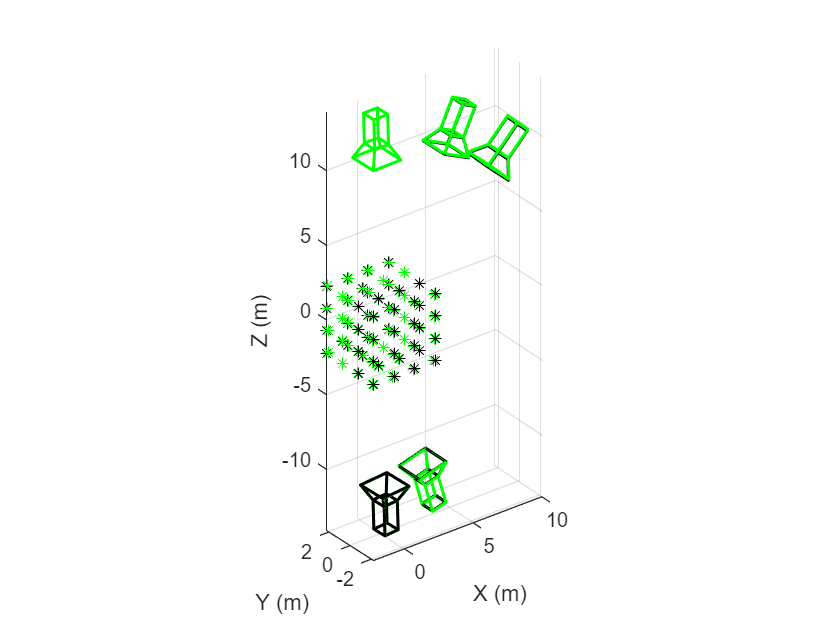

plot3d_rs(refined_RSBA_weighted_normal, gt_camera_param_normal, p3d_gt, p3d, pram, 'green', 'g*')

    
% -------------- N-RSBA --------------      
[refined_RSBA_normal] = RSBA_normal(camera_normal_param, pram,camera_set_normal);
[refined_RSBA_normal] = AdjustWithScale(refined_RSBA_normal, gt_camera_param_normal, pram);
figure
p3d_gt = getPoint(gt_camera_param_normal, pram);
p3d = getPoint(refined_RSBA_normal, pram);
error_nmrsba = sum(sum((p3d_gt - p3d) .* (p3d_gt - p3d)))

error_nmrsba = 164.2559

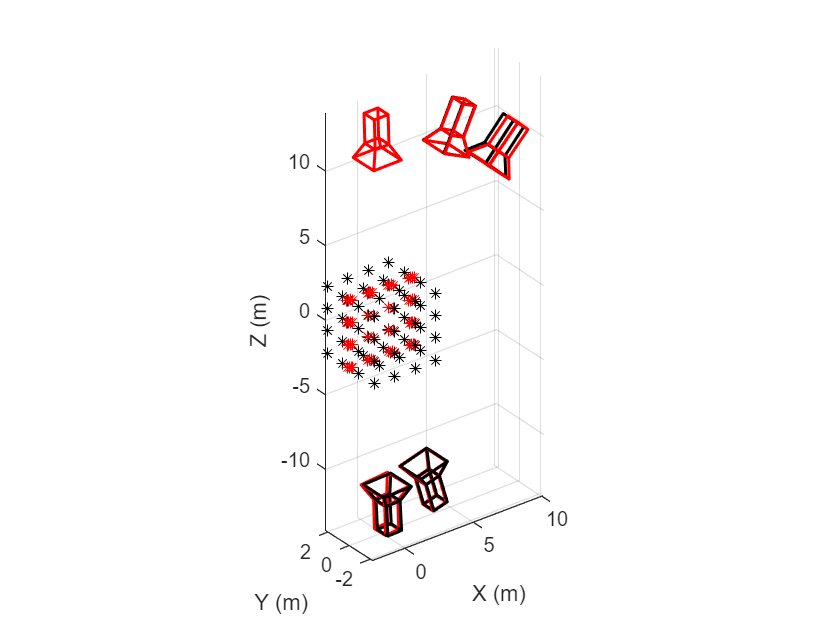

plot3d_rs(refined_RSBA_normal, gt_camera_param_normal, p3d_gt, p3d, pram, 'red', 'r*')



% -------------- CRSBA --------------
[refined_CRSBA] = CRSBA(camera_param, pram,camera_set);
[refined_CRSBA] = AdjustWithScale(refined_CRSBA, gt_camera_param, pram);
figure
p3d_gt = getPoint(gt_camera_param, pram);
p3d = getPoint(refined_CRSBA, pram);
error_crsba = sum(sum((p3d_gt - p3d) .* (p3d_gt - p3d)))

error_crsba = 11.7053

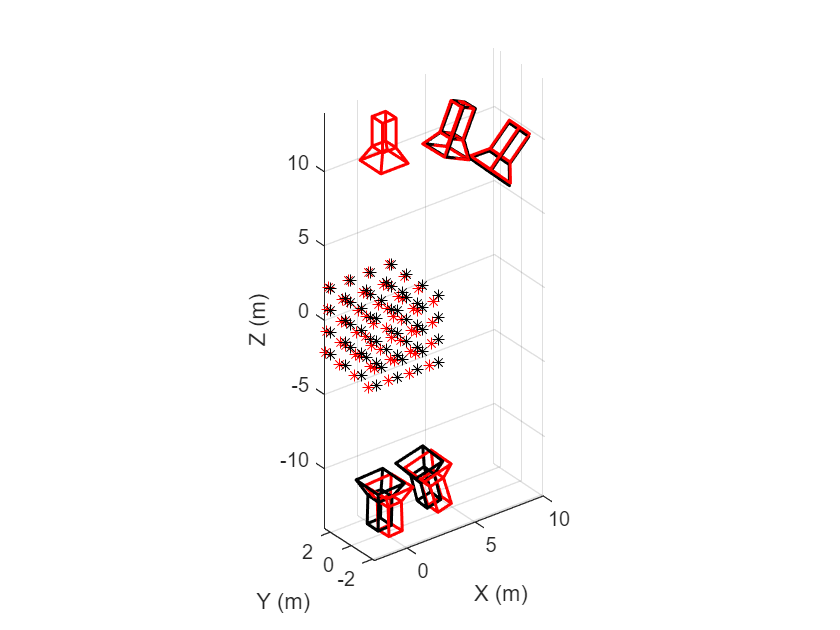

plot3d_rs(refined_CRSBA, gt_camera_param, p3d_gt, p3d, pram, 'red', 'r*')

function [x] = RSBA(cam_point_prama, pram, camera_set)
    OPTIONS = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt','Display','none');
    cam_fir = cam_point_prama(1:6);
    cam_oth = cam_point_prama(7:end);
    [x] = lsqnonlin(@(x)mrsba_opter(x,cam_fir,pram, camera_set),cam_oth,[],[],OPTIONS);
    x = [cam_fir x];

end
function [x] = RSBA_normal(cam_point_prama, pram, camera_set)
    OPTIONS = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt','Display','none','SpecifyObjectiveGradient',true);
    cam_fir = cam_point_prama(1:6);
    cam_oth = cam_point_prama(7:end);
    [x] = lsqnonlin(@(x)nmrsba_opter(x,cam_fir,pram, camera_set),cam_oth,[],[],OPTIONS);
    x = [cam_fir x];
end

function [x] = RSBA_weighted_normal(cam_point_prama, pram, camera_set)
    OPTIONS = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt','Display','none','SpecifyObjectiveGradient',true);
    cam_fir = cam_point_prama(1:6);
    cam_oth = cam_point_prama(7:end);
    [x] = lsqnonlin(@(x)nwrsba_opter(x,cam_fir,pram, camera_set),cam_oth,[],[],OPTIONS);
    x = [cam_fir x];
end

    
function [x] = RSBA_weighted(cam_point_prama, pram, camera_set)
    OPTIONS = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt','Display','none','SpecifyObjectiveGradient',true);
    cam_fir = cam_point_prama(1:6);
    cam_oth = cam_point_prama(7:end);
    [x] = lsqnonlin(@(x)wmrsba_opter(x,cam_fir,pram, camera_set),cam_oth,[],[],OPTIONS);
    x = [cam_fir x];
end


function [x] = CRSBA(cam_point_prama, pram, camera_set)
    OPTIONS = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt','Display','none');
    cam_fir = cam_point_prama(1:6);
    cam_oth = cam_point_prama(7:end);
    [x] = lsqnonlin(@(x)crsba_opter(x,cam_fir,pram, camera_set),cam_oth,[],[],OPTIONS);
    x = [cam_fir x];
end

   

function x = GSBA(camera_param, pram, camera_set)
    OPTIONS = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt','Display',"none");
    for i = 1:pram.num_camera
        id = (i - 1) * 12 + 1;
        id_c = (i - 1) * 6 + 1;
        cam_oth(1, id_c:id_c + 5) = camera_param(1, id:id + 5);
        w_d_oth(1, id_c:id_c + 5) = camera_param(1, id + 6:id + 11);
    end
    cam_oth = [cam_oth(7:end) camera_param(1, 12 * pram.num_camera + 1:end)];
    cam_fir = camera_param(1:6);
    
    [x] = lsqnonlin(@(x)gsba_opter(x, cam_fir ,pram, camera_set),cam_oth,[],[],OPTIONS);
    x = [cam_fir x];
    point = x(pram.num_camera * 6 + 1:end);
    for i = 1:pram.num_camera
        id_c = (i - 1) * 6 + 1;
        id = (i - 1) * 12 + 1;
        tmp_x(1, id:id + 5) = x(1, id_c:id_c + 5);
        tmp_x(1, id + 6:id + 11) = w_d_oth(1, id_c:id_c + 5);
    end
    x = [tmp_x point];
end

function [camera_param_adjusted, scale] = AdjustWithScale(camera_param, gt_camera_param, pram)
    camera_param_adjusted = camera_param;
    num_camera = pram.num_camera;
    num_points_all = pram.num_points_all;
    scale_gt = 0;
    scale = 0;
    gt_camera_t_fir = gt_camera_param(1, 4:6);
    gt_camera_r_fir = gt_camera_param(1, 1:3);
    gt_camera_r_fir = axang2rotm([gt_camera_r_fir / norm(gt_camera_r_fir) norm(gt_camera_r_fir)]);
    for i = 2:num_camera
        id = (i - 1) * 12 + 1;
        gt_camera_rota = gt_camera_param(1, id:id + 2);
        gt_camera_r = axang2rotm([gt_camera_rota / norm(gt_camera_rota) norm(gt_camera_rota)]);
        gt_camera_tran = gt_camera_param(1, id + 3:id + 5);
        gt_camera_t = gt_camera_r' * gt_camera_tran' - gt_camera_r_fir' * gt_camera_t_fir';
        scale_gt = scale_gt + norm(gt_camera_t);
    end
    for i = 2:num_camera
        id = (i - 1) * 12 + 1;
        camera_rota = camera_param(1, id:id + 2);
        camera_r = axang2rotm([camera_rota / norm(camera_rota) norm(camera_rota)]);
        camera_tran = camera_param(1, id + 3:id + 5);
        camera_t = camera_r' * camera_tran' - gt_camera_r_fir' * gt_camera_t_fir';
        scale = scale + norm(camera_t);
    end
    scale = scale_gt / scale;
    for i = 2:num_camera
        id = (i - 1) * 12 + 1;
        camera_rota = camera_param(1, id:id + 2);
        camera_r = axang2rotm([camera_rota / norm(camera_rota) norm(camera_rota)]);
        camera_tran = camera_param(1, id + 3:id + 5);
        camera_t = camera_r' * camera_tran' - gt_camera_r_fir' * gt_camera_t_fir';
        camera_t = camera_t * scale;
        camera_tran = camera_r * (camera_t + gt_camera_r_fir' * gt_camera_t_fir');
        camera_param_adjusted(1, id + 3:id + 5) = camera_tran';
        camera_param_adjusted(1, id + 9:id + 11) = camera_param_adjusted(1, id + 9:id + 11) * scale;
    end
    for i = 1:num_points_all
        id = num_camera * 12 + (i - 1) * 3 + 1;
        point = camera_param(1, id:id + 2);
        
        point = point + (gt_camera_r_fir' * gt_camera_t_fir')';
        camera_param_adjusted(1, id:id + 2) = point * scale - (gt_camera_r_fir' * gt_camera_t_fir')';
    end

end

